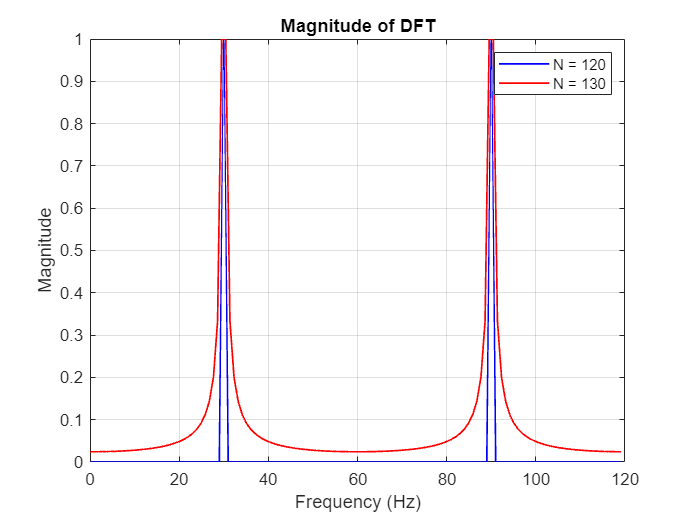

alpha = 1 + mod(286,3);
duration = 2;
sampling_rate = 120;
frequency = 15*alpha;
t = 0:1/sampling_rate:duration-1/sampling_rate;
signal = sin(2 * pi * frequency * t);
N1 = 120;
dft_120 = fft(signal(1:120));
dft_120 = dft_120/max(dft_120);
freq_120 = (0:N1-1) * (sampling_rate / N1);
N2 = 130;
dft_130 = fft(signal(1:130));
dft_130 = dft_130/max(dft_130);
freq_130 = (0:N2-1) * (sampling_rate / N2);

figure;
plot(freq_120, abs(dft_120), 'b', 'LineWidth', 1);
hold on;
plot(freq_130, abs(dft_130), 'r', 'LineWidth', 1);
title('Magnitude of DFT');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend('N = 120', 'N = 130');
grid on;
hold off;

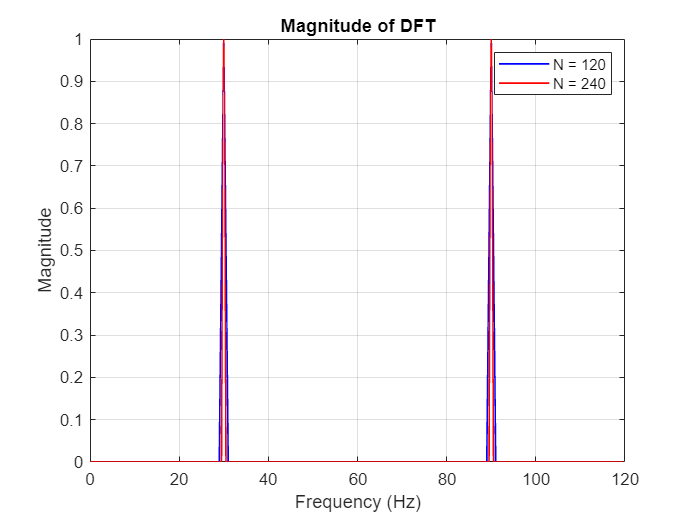


N3 = 240;
dft_240 = fft(signal(1:240));
dft_240 = dft_240/max(dft_240);
freq_240 = (0:N3 -1) * (sampling_rate / N3);

figure;
plot(freq_120, abs(dft_120), 'b', 'LineWidth', 1);
hold on;
plot(freq_240, abs(dft_240), 'r', 'LineWidth', 1);
title('Magnitude of DFT');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend('N = 120', 'N = 240');
grid on;
hold off;

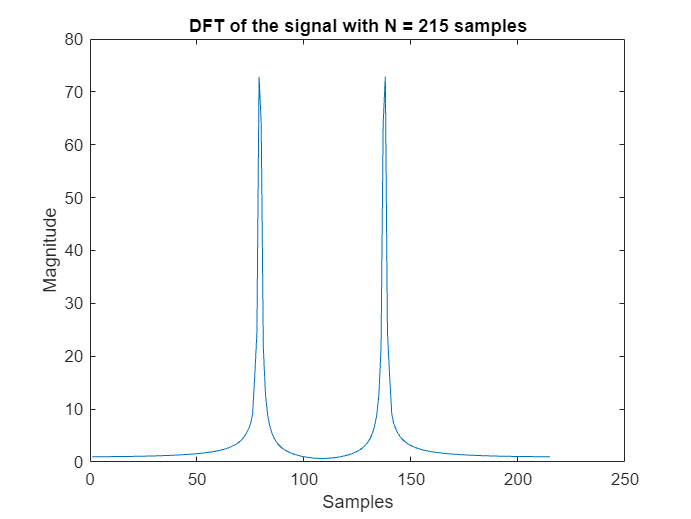

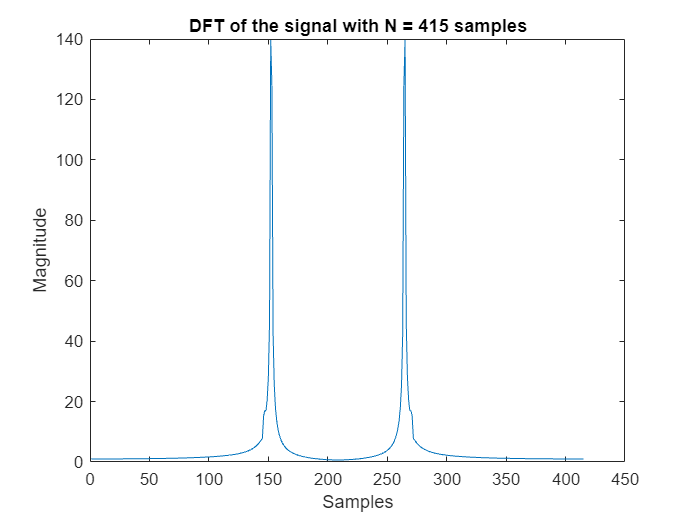

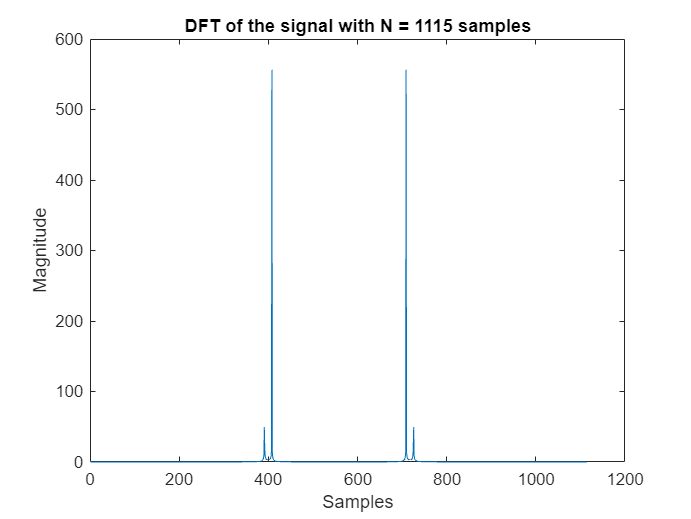

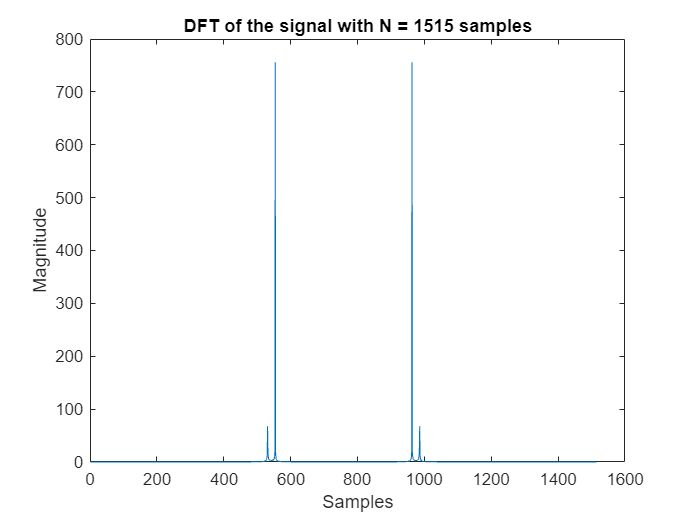

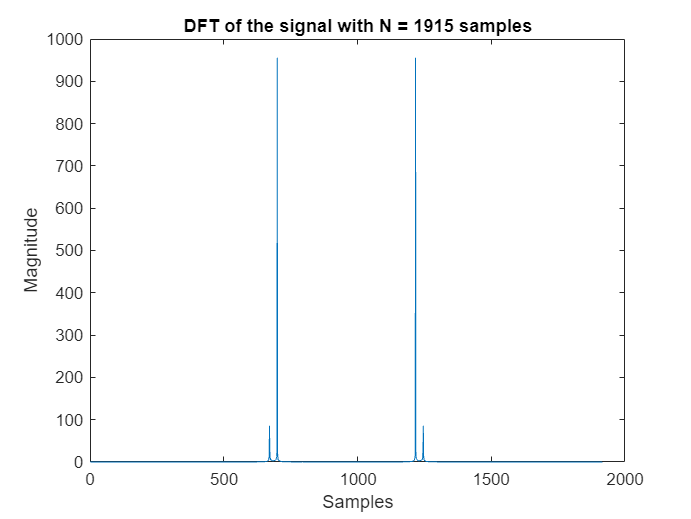

%Problem 2
A = 140;
B = 146;
duration = 10;
sampling_rate = 200; 

t = 0:1/sampling_rate:duration-1/sampling_rate;
signal = 0.1 * sin(A * pi * t) + cos(B * pi * t);

sample_sizes = [215, 415, 1115, 1515, 1915];

for i = 1:length(sample_sizes)
    N = sample_sizes(i);
    dft = fft(signal(1:N));
    figure;
    plot(abs(dft));
    xlabel('Samples');
    ylabel('Magnitude');
    title(sprintf('DFT of the signal with N = %d samples', N));

end

figure;

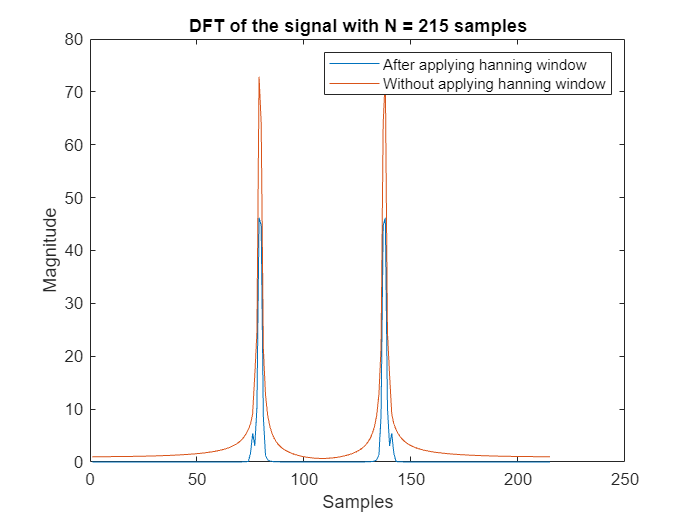

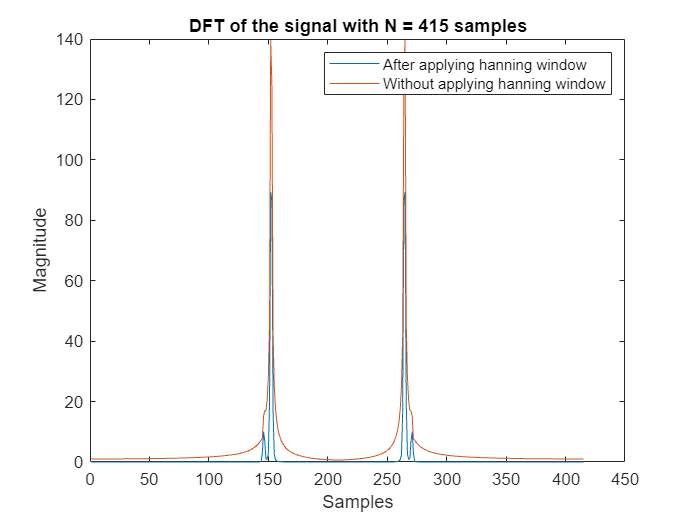

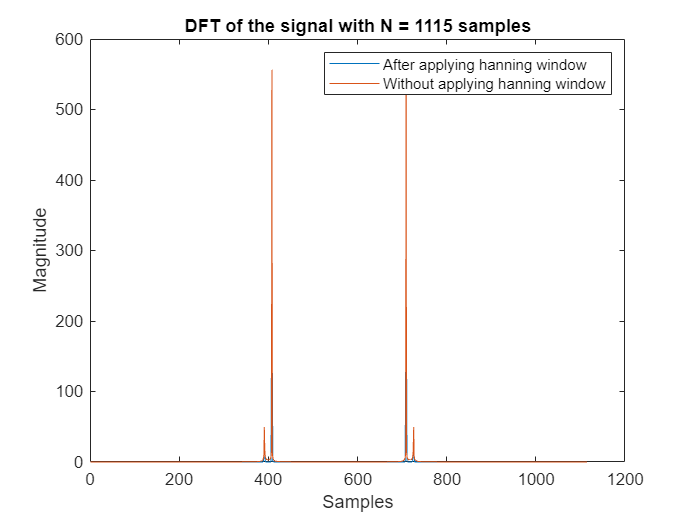

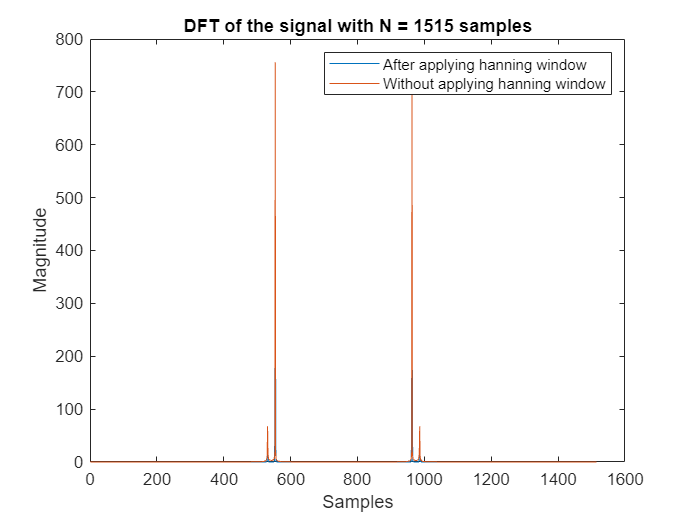

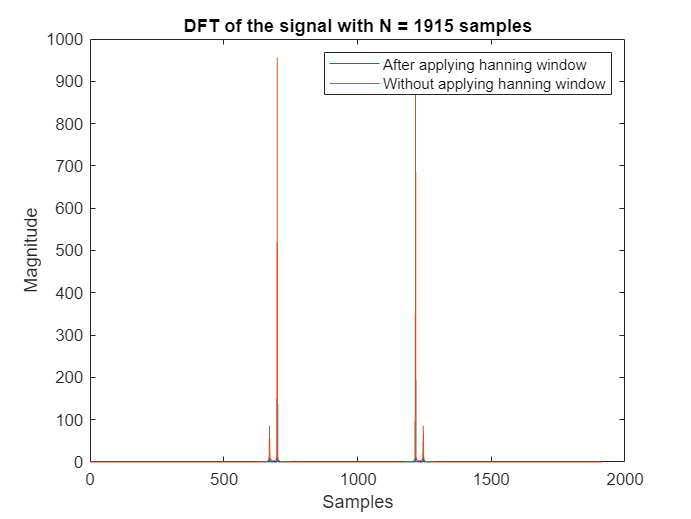

%Problem 3
for i = 1:length(sample_sizes)
    N = sample_sizes(i);
    sig = signal(1:N);

    window = hann(length(sig)).';
    windowed_signal = sig .* window;
    dft_og = fft(sig);
    dft = fft(windowed_signal);

    figure;
    plot(abs(dft));
    xlabel('Samples');
    ylabel('Magnitude');
    hold on;
    plot(abs(dft_og));
    legend('After applying hanning window','Without applying hanning window');
    hold off;
    title(sprintf('DFT of the signal with N = %d samples', N));

end

figure;

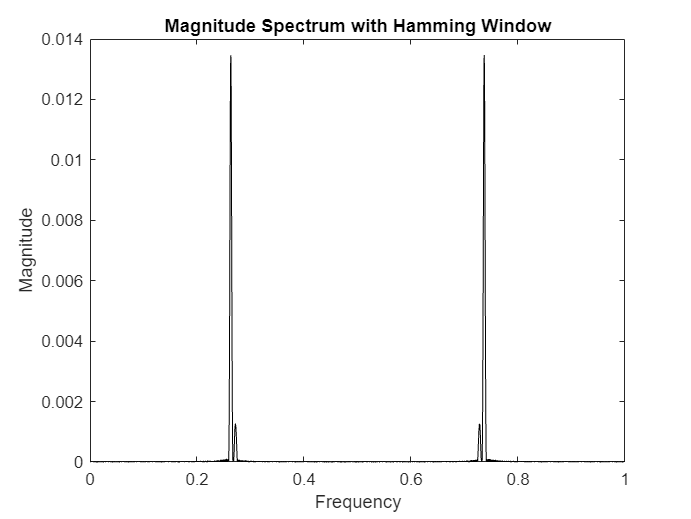

%Problem 4
data = load('C:\Users\charu\OneDrive\Desktop\College\DSP_Lab\Experiment-4\Exp4Data2.txt');
N = 500;

hamming_window = hamming(N);
rectangular_window = ones(N, 1);
hamming_windowed_data = data .* hamming_window';
rectangular_windowed_data = data .* rectangular_window';
N_fft = 10000;
fft_freq = (0:N_fft-1) / N_fft;
fft_hamming = fft(hamming_windowed_data, N_fft);
fft_rectangular = fft(rectangular_windowed_data, N_fft);

magnitude_spectrum_hamming = abs(fft_hamming)/N_fft;
magnitude_spectrum_rectangular = abs(fft_rectangular)/N_fft;

figure;
plot(fft_freq, magnitude_spectrum_hamming, 'k');
xlabel('Frequency');
ylabel('Magnitude');
title('Magnitude Spectrum with Hamming Window');

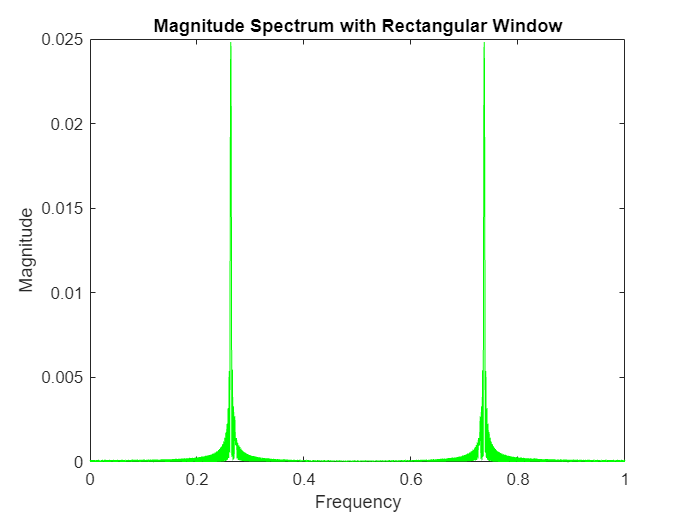


figure;
plot(fft_freq, magnitude_spectrum_rectangular, 'g');
xlabel('Frequency');
ylabel('Magnitude');
title('Magnitude Spectrum with Rectangular Window');


[~, peak_indices_hamming] = maxk(abs(fft_hamming(1:N)),2);
peak_frequencies_hamming = fft_freq(peak_indices_hamming);
disp('Estimated Frequencies using Hamming window:');

Estimated Frequencies using Hamming window:


disp(peak_frequencies_hamming);

    0.0480    0.0440




[~, peak_indices_rectangular] = maxk(abs(fft_rectangular(1:N)),2);
peak_frequencies_rectangular = fft_freq(peak_indices_rectangular);
disp('Estimated Frequencies using Rectangular window:');

Estimated Frequencies using Rectangular window:


disp(peak_frequencies_rectangular);

    0.0480    0.0460

